# Peridynamics Simulation - Transient Heat Conduction

## Custom Functions List

- generate_node_locations - This function is used to generate the node locations as an array in the domain.

- initialize_initial_temperature - This function is used to update the temperature array from the boundary conditions

- find_nodes_within_horizon - This function is used to find the nodes which are inside the specified horizon

- generate_interaction_id - This function is used to compute the interaction ids for the elements in the domain

- apply_bondary_condition: This function is used to apply the boundary condition values to the matrix solver

% Clear the variables initialized before
clear global;
clc;clear;

## Define the required Properties

**Thermal properties**

alpha=4.5e-5; % Thermal diffusivity

**Physical properties**

Domain_length = 0.1; % Length of the domain
Number_of_nodes = 100; % Number of nodes in the domain
no_of_neighbours = 3.015; % Number of neighbours (which can be changed by user)
Area = 1e-6;

**Simulation properties**

dt = 1; % Timesteps
t0 = 0; % Starting time
tf = 150; % Ending time 
time_array = t0 : dt : tf; % Array with all time values from start to end

% custom function to generate node locations in the domain
[X,element_width] = generate_node_locations(Domain_length,Number_of_nodes); 

horizon_length = no_of_neighbours * element_width;

% Tolerance value to stop the iteration
tolerance = 1e-10;

**Boundary Conditions**

**T = 0 at 1st node |-----------------------------------------| T = 100 at the last node**

global essential_boundary_condition_nodes essential_boundary_condition; % Set as global variables 
                                                                        % to be accessed by various functions
essential_boundary_condition = [1 0; Number_of_nodes 100]; % Storing the boundary conditions as 2d array
essential_boundary_condition_nodes = essential_boundary_condition(:,1); % Taking the first and last node separately
[T] = initialize_initial_temperature(Number_of_nodes);

## Peridynamics Simulation:

% Find the neighbouring nodes of the given element
[neighbours_of_element] = find_nodes_within_horizon(X,horizon_length);

% Generate the interaction ids for the elements in the domain
[interaction_id] = generate_interaction_id_matrix(X, neighbours_of_element);

total_number_of_interactions = length(interaction_id); % Store the total number of interactions of the domain

r = element_width/2;

### Volume Correction for the interactions

% Initialize the array variables to speed up calculations
volume_correction = zeros(total_number_of_interactions,1);
distance_of_interaction = zeros(total_number_of_interactions,1);

% Compute the volume correction terms and distance of interactions 
for interaction = 1 : total_number_of_interactions
    xj = X(interaction_id(interaction,1));
    xk = X(interaction_id(interaction,2));
    dist_interaction = norm(xk - xj);
    if dist_interaction >= horizon_length - r && dist_interaction <= horizon_length
        vol_corr = (horizon_length + r - dist_interaction)/(2*r); % Partial contribution of the element
    else
        vol_corr = 1; % Full contribution of the element
    end
    volume_correction(interaction) = vol_corr;
    distance_of_interaction(interaction) = dist_interaction; 
end

### Transient Solver (Implicit Solver)

Solving the linear system if equations AX = B

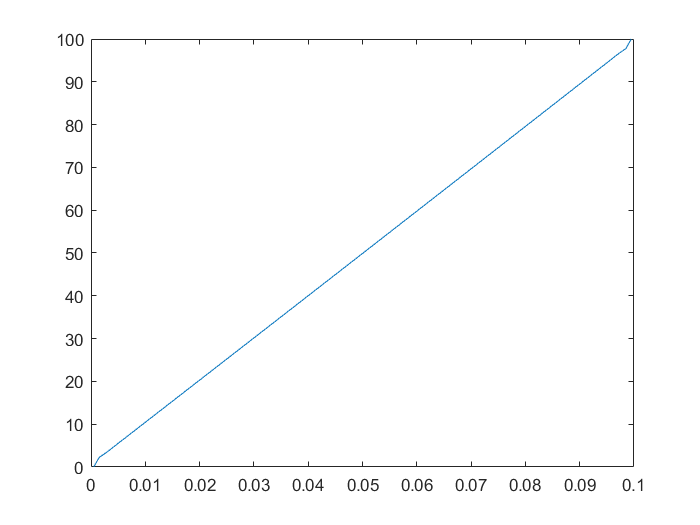

A = -eye(Number_of_nodes);
f = -ones(Number_of_nodes,1) .* T;
m = (2 * alpha * dt)/ (Area * horizon_length^2);
dV_j = element_width * Area;

% Populate the A matrix with the values for solving
for interaction = 2 : total_number_of_interactions
    k = interaction_id(interaction,2); % current node
    j = interaction_id(interaction,1); % neighbouring nodes
    A(k,j)= A(k,j) + (m / distance_of_interaction(interaction)) * volume_correction(interaction) * dV_j;
    A(k,k)= A(k,k) - (m / distance_of_interaction(interaction)) * volume_correction(interaction) * dV_j;
end

current_time = 0;
halfTemp = zeros(length(time_array)); % Initialize variable to speed up computation

% Simulating for the entire timesteps
for time = 1 : length(time_array)
    error_norm = 1;
    current_time = 0;
    while error_norm > tolerance
        b = f - A * T;
        [A1,b1] = apply_boundary_condition_to_solver(A,b);
        dT = linsolve(A1,b1); % Solve the system of equations
        T = T + dT; % Update the Temperature matrix
        error_norm = dT' * dT; % Compute the norm of the dT vector
        current_time = current_time + 1;
    end
    f = -T;
    halfTemp(time) = T(Number_of_nodes/2);
end

halfTemp(time) = T(Number_of_nodes/2);
figure(1)
(plot(X,T));
hold on

## Custom function definitions

- Generate node locations: This function sets the node locations of the elements in the domain.

function [X,element_width] = generate_node_locations(L,N) % Function to generate the spatial location of the nodes
    dx = L/N;
    X = dx/2 : dx : L - dx/2; % Fix the node locations at the element's centre
    element_width = abs(X(2) - X(1)); % Delta = dx 
end

         2. Initialize initial temperature: This function sets the temperature values from the essential boundary conditions

function [T] = initialize_initial_temperature(N)
    global essential_boundary_condition;
    T = zeros(N,1); % Variable to store the temperature values

    % Loop through all dimensions in the boundary conditions
    for i = 1 : size(essential_boundary_condition,1)
        node_location = essential_boundary_condition(i,1);
        T(node_location) = essential_boundary_condition(i,2);
    end
    
end

        3. find_nodes_within_horizon: This function is used to find the node values which are within the specifed horizon

function [neighbours_of_element] = find_nodes_within_horizon(X,horizon_length)

    for i = 1 : length(X)
        x = X(i); % Store the current value in the temporary variable
        distance = sqrt((X - x).^2); % find the distance between the vectors and current vector
        neighbour_indices = find(distance <= horizon_length); % Store the neighbour indices in an array 
        self_id = find(neighbour_indices == i);
        neighbour_indices(self_id) = []; % Remove the self id node from the list
        neighbours_of_element{i} = neighbour_indices;
    end
    
end

         4. generate_interaction_id: This function is used to create the interaction matrix for the domain:

             The matrix is such that first element is j (neighbour) and second element is k (current node)

function [interaction_id] = generate_interaction_id_matrix(X,neighbours_of_element)
    iterator = 1; % Just a temporary iterator for the cummulative interaction id
    
    for current_node = 1 : length(X)
        for neighbours = 1 : length(neighbours_of_element{current_node})
            interaction_id(iterator,:) = [neighbours_of_element{current_node}(neighbours) current_node];
            iterator = iterator + 1;
        end
    end
end

         5. apply_boundary_condition: This function is used to apply the boundary condition values to the matrix solver

function [A1,b1] = apply_boundary_condition_to_solver(A,b)
    global essential_boundary_condition_nodes;
    A1 = A;
    b1 = b;
    if(~isempty(essential_boundary_condition_nodes))
        
        for node = 1 : length(essential_boundary_condition_nodes)
            node_id = essential_boundary_condition_nodes(node);
            A(:,node_id) = 0;
            A(node_id,:) = 0;
            A(node_id,node_id) = 1;
            b(node_id,1) = 0;
        end
    else
        return;
    end
    A1 = A;
    b1 = b;
end
